# **Assignment 2 - Finite Difference Method**

## **Question 1. a)** Finite Difference used to solve $\nabla^2 V=0$

G Matrix formed to a set of linear equations, each representing a node in a rectangular region.

F Matrix represents the independent elements which is a source.

Solving the simple case where:

- V = 1 @ x = 0

- V = 0 @ x = nx

- The length or y is unconstrained (i.e. floating)

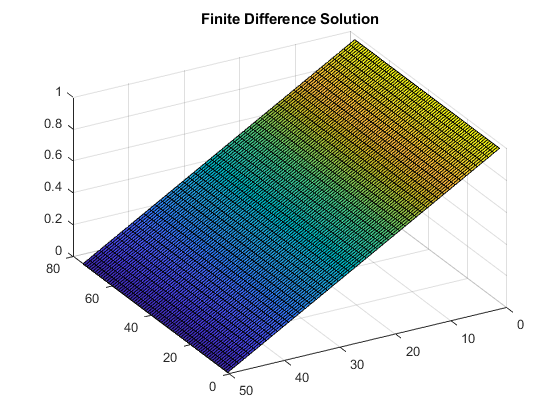

nx = 50;   % # of colums
ny = 75;   % # of rows
G = sparse(nx*ny,ny*nx);
F = zeros(nx*ny,1);
for i = 1:nx
    for j = 1:ny
        
        n = j + (i-1) * ny;     % middle
        nxm = j + (i-2) * ny;	% right
        nxp = j + i * ny;       % left
        nym = j-1 + (i-1) * ny; % top
        nyp = j+1 + (i-1) * ny; % down
        
        if i == 1
            G(n,n) = 1;
            F(n,1) = 1;
        elseif i == nx
            G(n,n) = 1;
            F(n,1) = 0;
        elseif j == 1
            G(n,n) = -3;
            G(n,nxm) = 1;
            G(n,nxp) = 1;
            G(n,nyp) = 1;
        elseif j == ny
            G(n,n) = -3;
            G(n,nxm) = 1;
            G(n,nxp) = 1;
            G(n,nym) = 1;
        else
            G(n,n) = -4;
            G(n,nxm) = 1;
            G(n,nxp) = 1;
            G(n,nym) = 1;
            G(n,nyp) = 1;
        end
        
    end
end

% Solving the set of linear equations to obtain voltage values
dA = decomposition(G,'lu');
V = dA\F;
Vmap = reshape(V, [ny, nx]);    % Reshaping Vector to a matrix
figure('name', 'Finite Difference Solution');
surf(Vmap'), title('Finite Difference Solution'); % Plotting

view([-119.400 40.200])

## **Question 1. b)** Finite Difference Method compared with an Analytical Solution

The FD created will be used to solve the region with these constraints:

- V = 1 @ x = 0

- V = 1 @ x = nx

- V = 0 @ y = 0

- V = 0 @ y = ny

The solution is then compared with an analytical solution to the region defined by:

        L = 300, W = 200

        
$$V\left(x,y\right)=4\frac{V_0 }{\pi \;}\sum_{n=1,3,5\ldotp \ldotp \ldotp } \frac{1}{n}\frac{\mathrm{cosh}\left(\frac{n\pi x}{a}\right)}{\mathrm{cosh}\left(\frac{n\pi b}{a}\right)}\;\mathrm{sin}\left(\frac{n\pi y}{a}\right),\mathrm{where}\;a=L\;\mathrm{and}\;b=\frac{W}{2}$$
 

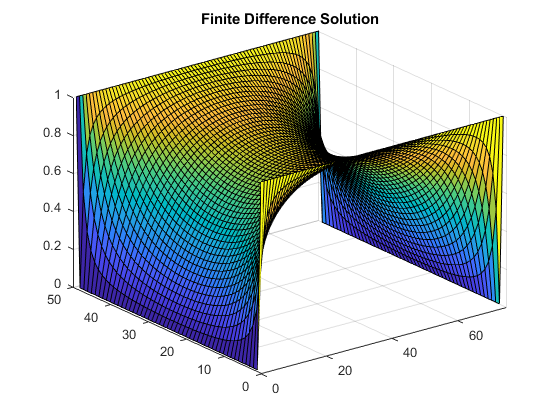

G = sparse(nx*ny,ny*nx);
F = zeros(nx*ny,1);
for i = 1:nx
    for j = 1:ny
        
        n = j + (i-1) * ny;     % middle
        nxm = j + (i-2) * ny;	% right
        nxp = j + i * ny;       % left
        nym = j-1 + (i-1) * ny; % top
        nyp = j+1 + (i-1) * ny; % down
        
        if i == 1
            G(n,n) = 1;
            F(n,1) = 1;
        elseif i == nx
            G(n,n) = 1;
            F(n,1) = 1;
        elseif j == 1 
            G(n,n) = 1;
            F(n,1) = 0;
        elseif j == ny
            G(n,n) = 1;
            F(n,1) = 0;
        else
            G(n,n) = -4;
            G(n,nxm) = 1;
            G(n,nxp) = 1;
            G(n,nym) = 1;
            G(n,nyp) = 1;
        end
        
    end
end

% Solving the set of linear equations to obtain voltage values
dA = decomposition(G,'lu');
V = dA\F;
Vmap = reshape(V, [ny nx]);    % Reshaping Vector to a matrix
figure('name', 'Finite Difference Solution');
surf(Vmap'), title('Finite Difference Solution');
xlim([0,ny]),ylim([0,nx]),zlim([0 1]);

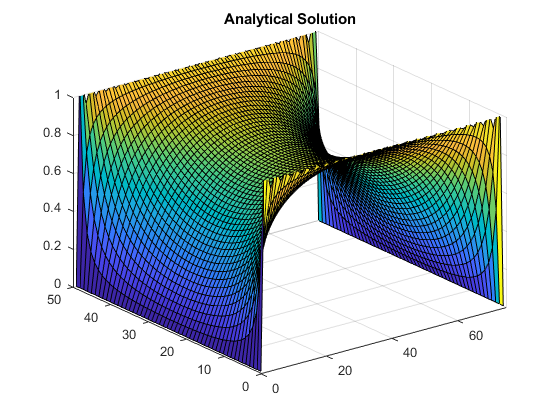

% ANALYTICAL SOLUTION
L = 300;
W = 200;
a = L;
b = W/2;
x = linspace(-b, b, nx);
y = linspace(0, a, ny);
V = zeros(ny, nx);

figure('name', 'Analytical Solution')
[X,Y] = meshgrid(x,y);
for n = 1:2:99
    V = V + ( (1/n) * (cosh((n*pi*X)/a)/cosh((n*pi*b)/a)) ...
                    .* sin((n*pi*Y)/a) );
    surf(4/pi*V'), title('Analytical Solution')
    xlim([0,ny]),ylim([0,nx]),zlim([0 1]);
    pause(0.01);
end

## **Question 2. a)** Finite Difference Method to Solve for Current Flow

The finite difference solver created in Q1 is modified to include a conduction map. The model of the rectangular region is hence expanded to include a resistive element between each node. In addition, a bottleneck is applied to the conductivity which presents a difference in conductivity in a specified region.

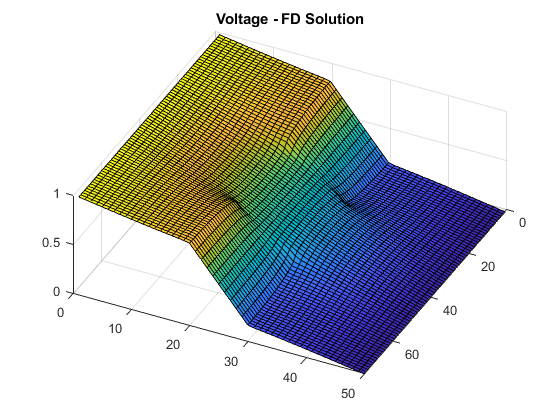

global cMap
boxL = 10;      % Length of box... along x
boxW = 25;      % Width of box... along y
sigma = 0.1;    % Conductivity of box
% Function Call
V = Assignment2_Q2(nx, ny, boxL, boxW, sigma);

% Potential Surface Map
vMap = reshape(V, [ny nx]);    % Reshaping Vector to a matrix
figure('name', 'Voltage - FD Solution');
surf(vMap'), title('Voltage - FD Solution'); % Plotting
xlim([0,ny]),ylim([0,nx]),zlim([0 1]);
view([-243.900 61.800])

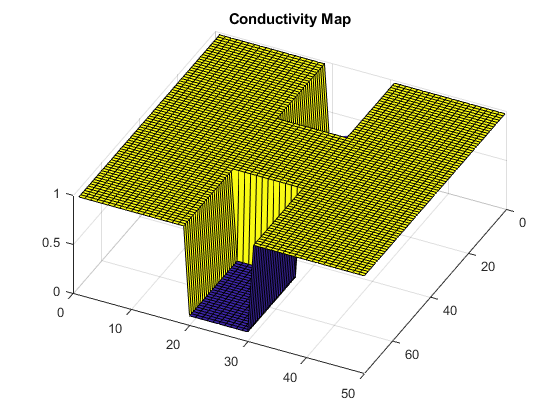

% Conductivity Map
figure('name', 'Conductivity Map');
surf(cMap), title('Conductivity Map');
xlim([0,ny]),ylim([0,nx]),zlim([0 1]);
view([-243.900 61.800])

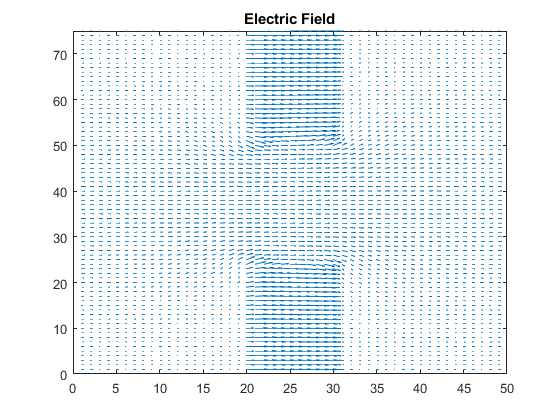

% Electric Field
[Ex,Ey] = gradient(-vMap);
figure('name', 'Electric Field');
quiver(Ex,Ey,1.1), title('Electric Field');
xlim([0,nx]),ylim([0,ny]);

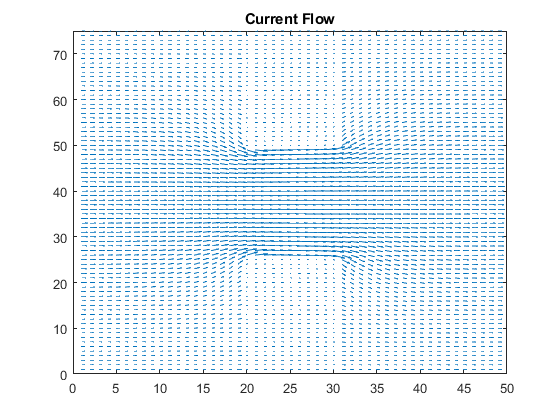

% Current Flow
Jx = cMap'.* Ex;
Jy = cMap'.* Ey;
figure('name', 'Current Flow');
quiver(Jx,Jy,1.1), title('Current Flow');
xlim([0,nx]),ylim([0,ny]);

## **Question 2. b)** Effect of Mesh Size on Current in the region

To investigate the effect of mesh density, the size of the mesh is increased and the mean of the currents in the region at each mesh size is recorded. The mesh size as well as the size of the bottleneck is increased by a linearly increasing multiplier. 

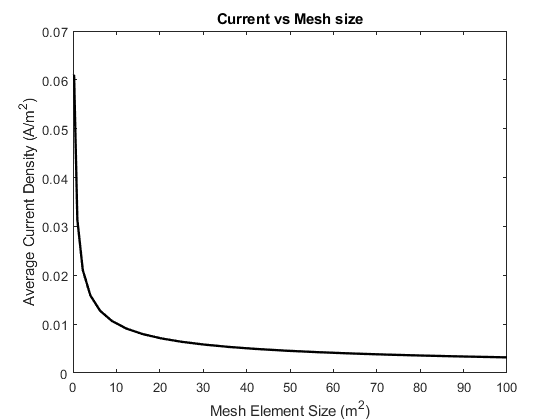

meshMul = 0.5:0.5:10;
currents = zeros(size(meshMul,2), 1);
areas = zeros(size(meshMul,2), 1);

for i = 1:size(meshMul,2)
    nx = 20 * meshMul(i);
    ny = 30 * meshMul(i);
    boxL = 4 * meshMul(i);
    boxW = 10 * meshMul(i);
    
    V = Assignment2_Q2(nx, ny, boxL, boxW, 0.1);
    
    vMap = reshape(V, [ny nx]);
    J = cMap'.*gradient(-vMap);
    
    currents(i,1) = mean(J, 'all');
    areas(i,1) = (nx/20)*(ny/30);
end

plot(areas,currents, 'k', 'LineWidth',1.75);
xlabel('Mesh Element Size (m^2)');
ylabel('Average Current Density (A/m^2)');
title('Current vs Mesh size');

As the mesh size increases the current density seems to converge to a value. Assuming the region being represented is not increasing, this relationship shows how a higher density mesh will result in more accurate results. However, increasing the density increases the simulation time quite drastically which can result in diminishing returns.

## **Question 2. c)** Effect of Narrowing the Bottleneck

To investigate the effect of narrowing the bottleneck in the region, the width of the box is increased and the maximum current value is recorded at every step.

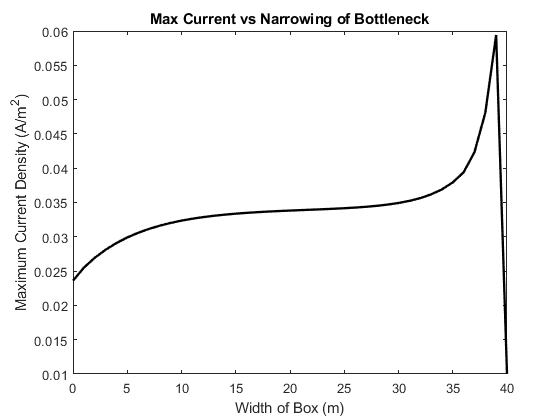

nx = 50;        % # of colums
ny = 80;        % # of rows
boxL = 10;
boxW = 0:1:40;
currents = zeros(size(boxW,2), 1);

for i = 1:size(boxW,2)
    
    V = Assignment2_Q2(nx, ny, boxL, boxW(i), 0.1);
    
    vMap = reshape(V, [ny nx]);
    J = cMap'.*gradient(-vMap);
    currents(i,1) = max(J, [], 'all');
end

plot(boxW,currents, 'k', 'LineWidth',1.75);
xlabel('Width of Box (m)');
ylabel('Maximum Current Density (A/m^2)');
title('Max Current vs Narrowing of Bottleneck');

As the box narrows the maximum value increases. As the bottleneck comes very close to cutting of the maximum current reaches a very high value before being completely cut-off.

## **Question 2. d)** Effect of the conductivity inside the box

To investigate the effect of the conductivity inside the box, the region is left at its nominal value while the $\sigma_{\mathrm{Box}}$ of the box is increased.

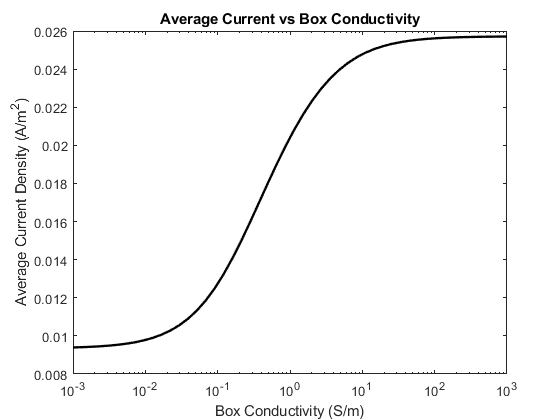

nx = 50;        % # of colums
ny = 75;        % # of rows
boxL = 10;
boxW = 25;
sigma = logspace(-3,3);
currents = zeros(size(sigma,2), 1);

for i = 1:size(sigma,2)
    
    V = Assignment2_Q2(nx, ny, boxL, boxW, sigma(i));
    
    vMap = reshape(V, [ny nx]);
    J = cMap'.*gradient(-vMap);
    currents(i,1) = mean(J, 'all');
end

plot(sigma,currents, 'k', 'LineWidth',1.75);
set(gca, 'XScale', 'log');
xlabel('Box Conductivity (S/m)');
ylabel('Average Current Density (A/m^2)');
title('Average Current vs Box Conductivity');

The $\sigma_{\mathrm{Box}}$ is increased logarithmically from ${10}^{-3} -{10}^3$. As the conductivity approaches the conductivity of the region at 1, the average current density quicky increases. As the conductivity further increases, the current in the region begins to saturate. When $\sigma_{\mathrm{region}} =\sigma_{\mathrm{Box}} \;$the solution is effectively the same as Q1.b.

function [V] = Assignment2_Q2(nx, ny, boxL, boxW, sigma)
    
    % Conductivity Map
    global cMap
    cMap = ones(nx,ny);
    cMap(nx/2 - boxL/2:nx/2 + boxL/2,1:boxW) = sigma;
    cMap(nx/2 - boxL/2:nx/2 + boxL/2,ny-boxW:ny) = sigma;
    
    G = sparse(nx*ny,ny*nx);
    F = zeros(nx*ny,1);
    for i = 1:nx
        for j = 1:ny

            % Node Mapping
            n = j + (i-1) * ny;     % middle
            nxm = j + (i-2) * ny;	% right
            nxp = j + i * ny;       % left
            nym = j-1 + (i-1) * ny; % top 
            nyp = j+1 + (i-1) * ny; % down

            if i == 1
                G(n,n) = 1;
                F(n,1) = 1;
            elseif i == nx
                G(n,n) = 1;
            elseif j == 1
                rxm = (cMap(i,j) + cMap(i-1,j)) / 2;
                rxp = (cMap(i,j) + cMap(i+1,j)) / 2;
                ryp = (cMap(i,j) + cMap(i,j+1)) / 2;

                G(n,n) = -(rxm+rxp+ryp);
                G(n,nxm) = rxm;
                G(n,nxp) = rxp;
                G(n,nyp) = ryp;
            elseif j == ny
                rxm = (cMap(i,j) + cMap(i-1,j)) / 2;
                rxp = (cMap(i,j) + cMap(i+1,j)) / 2;
                rym = (cMap(i,j) + cMap(i,j-1)) / 2;

                G(n,n) = -(rxm+rxp+rym);
                G(n,nxm) = rxm;
                G(n,nxp) = rxp;
                G(n,nym) = rym;
            else
                rxm = (cMap(i,j) + cMap(i-1,j)) / 2;
                rxp = (cMap(i,j) + cMap(i+1,j)) / 2;
                rym = (cMap(i,j) + cMap(i,j-1)) / 2;
                ryp = (cMap(i,j) + cMap(i,j+1)) / 2;

                G(n,n) = -(rxm+rxp+rym+ryp);
                G(n,nxm) = rxm;
                G(n,nxp) = rxp;
                G(n,nym) = rym;
                G(n,nyp) = ryp;
            end

        end
    end

    % Solving the set of linear equations to obtain voltage values
    dA = decomposition(G,'lu');
    V = dA\F;   % Return vector of potentials
end

